dVec = 0:0.01:0.9;
mVec = -dVec ./ (1-dVec) ;

figure (1)
plot( dVec, mVec);
ylabel("TesY")
xlabel("TesX")
title("Title")
grid("on")


%gkjsya

Vin         = 12;       %V
fsw         = 50e3;     %Hz
T           = 1/fsw;
L1          = 330e-6;   %H
C1          = 83e-6;    %F
R_load      = 10;       %Ohm

Plot Vc and IL

Vc_vec = -dVec ./ (1-dVec) * Vin;
Il_vec = -1 ./ (1-dVec) .* (Vc_vec / R_load) 

Il_vec =          0    0.0122    0.0250    0.0383    0.0521    0.0665    0.0815    0.0971    0.1134    0.1304    0.1481    0.1666    0.1860    0.2061    0.2271    0.2491    0.2721    0.2961    0.3212    0.3475    0.3750    0.4038    0.4339    0.4655    0.4986    0.5333    0.5698    0.6080    0.6481    0.6903    0.7347    0.7813    0.8304    0.8822    0.9366    0.9941    1.0547    1.1187    1.1863    1.2577    1.3333    1.4134    1.4982    1.5882    1.6837    1.7851    1.8930    2.0078    2.1302    2.2607



subplot(2,1,1)
plot(dVec, Vc_vec)
ylabel("V_C")
grid('on')
subplot(2,1,2)
plot(dVec, Il_vec)
xlabel('D')
ylabel('I_L[A]')
grid("on")

Stromripple


$$\Delta i_L = \frac{1}{2} \cdot D \cdot T \cdot \frac{V_in}{L}$$


Spannungsripple


$$\Delta v_C = \frac {1}{2} \cdot D \cdot T \cdot \frac{-I_R}{C} = \frac {1}{2} \cdot D \cdot T \cdot \frac{-V_C}{R \cdot C}$$


dil_vec = 0.5 * dVec * T *  Vin / L1

dil_vec =          0    0.0036    0.0073    0.0109    0.0145    0.0182    0.0218    0.0255    0.0291    0.0327    0.0364    0.0400    0.0436    0.0473    0.0509    0.0545    0.0582    0.0618    0.0655    0.0691    0.0727    0.0764    0.0800    0.0836    0.0873    0.0909    0.0945    0.0982    0.1018    0.1055    0.1091    0.1127    0.1164    0.1200    0.1236    0.1273    0.1309    0.1345    0.1382    0.1418    0.1455    0.1491    0.1527    0.1564    0.1600    0.1636    0.1673    0.1709    0.1745    0.1782


dvc_vec = 0.5 * dVec * T .* (-Vc_vec) / (R_load * C1)

dvc_vec =          0    0.0000    0.0001    0.0001    0.0002    0.0004    0.0006    0.0008    0.0010    0.0013    0.0016    0.0020    0.0024    0.0028    0.0033    0.0038    0.0044    0.0050    0.0057    0.0064    0.0072    0.0081    0.0090    0.0099    0.0110    0.0120    0.0132    0.0144    0.0157    0.0171    0.0186    0.0201    0.0218    0.0235    0.0253    0.0272    0.0293    0.0314    0.0337    0.0360    0.0386    0.0412    0.0440    0.0469    0.0500    0.0532    0.0567    0.0603    0.0641    0.0681


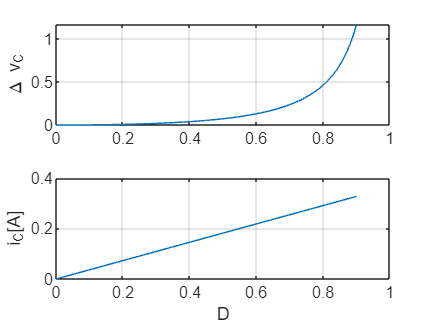


subplot(2,1,1)
plot(dVec, dvc_vec)
ylabel("\Delta v_C")
grid('on')
subplot(2,1,2)
plot(dVec, dil_vec)
xlabel('D')
ylabel('i_C[A]')
grid("on")

Calculate all values for D = 0.5

D = 0.5

D = 0.5000

Vc = -D ./ (1-D) * Vin

Vc = -12

Il = -1 ./ (1-D) .* (Vc / R_load)

Il = 2.4000

dil = 0.5 * D * T * Vin/L1

dil = 0.1818

dvc = 0.5 * D * T .* (-Vc)/(R_load*C1)

dvc = 0.0723

ElCap selection

Vishay 136 RVI

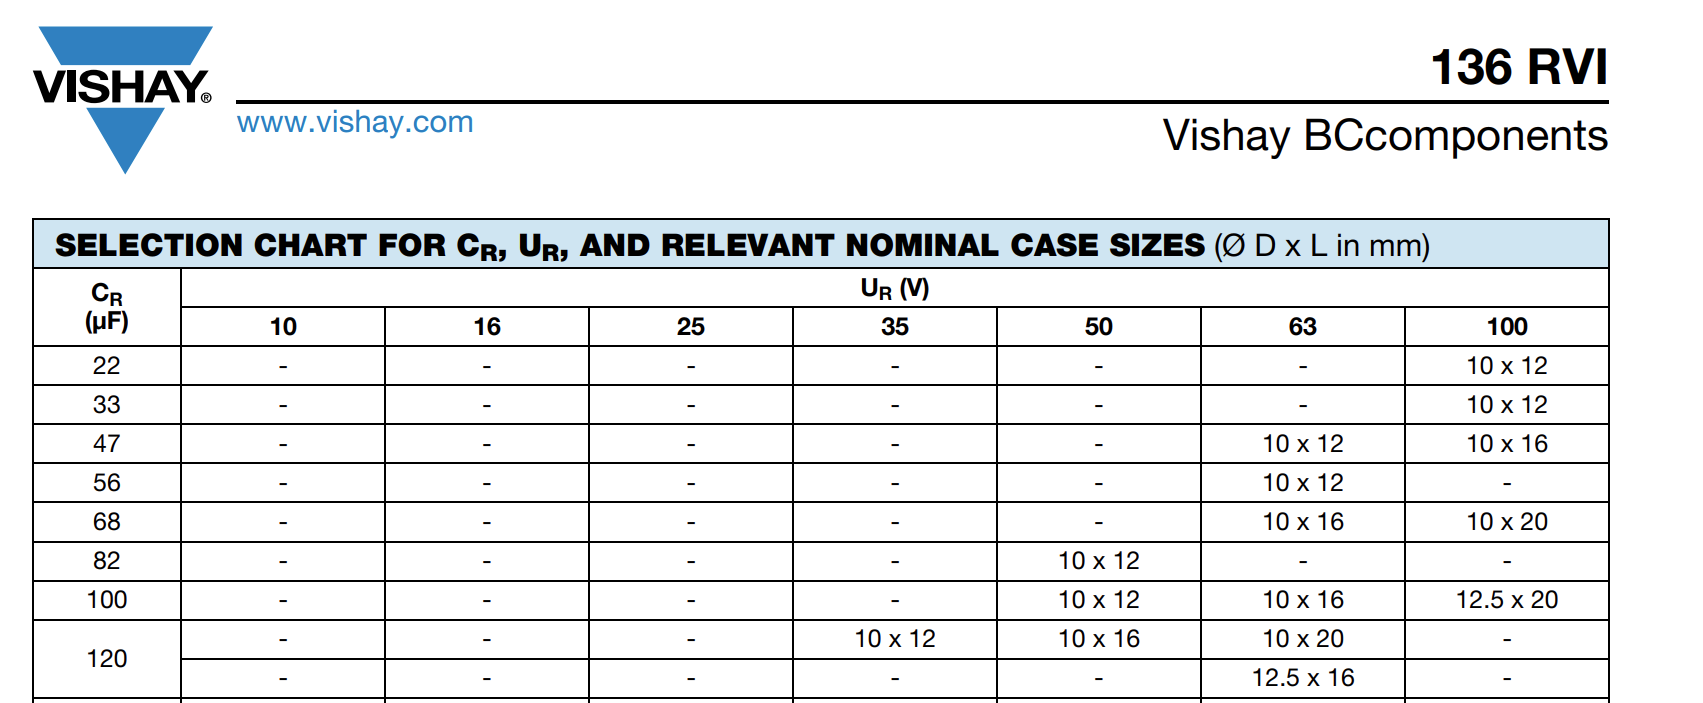

$U_r = 50V$ case 10x12mm


$$Z = \sqrt{R^2 + X_C^2}$$


Z_100kHz        = 0.4;      %Ohm
XC_100kHz       = 1/(2*pi*100e3*C1) %Ohm

XC_100kHz = 0.0192


ESR_100kHz      = sqrt (Z_100kHz^2 - XC_100kHz^2)

ESR_100kHz = 0.3995

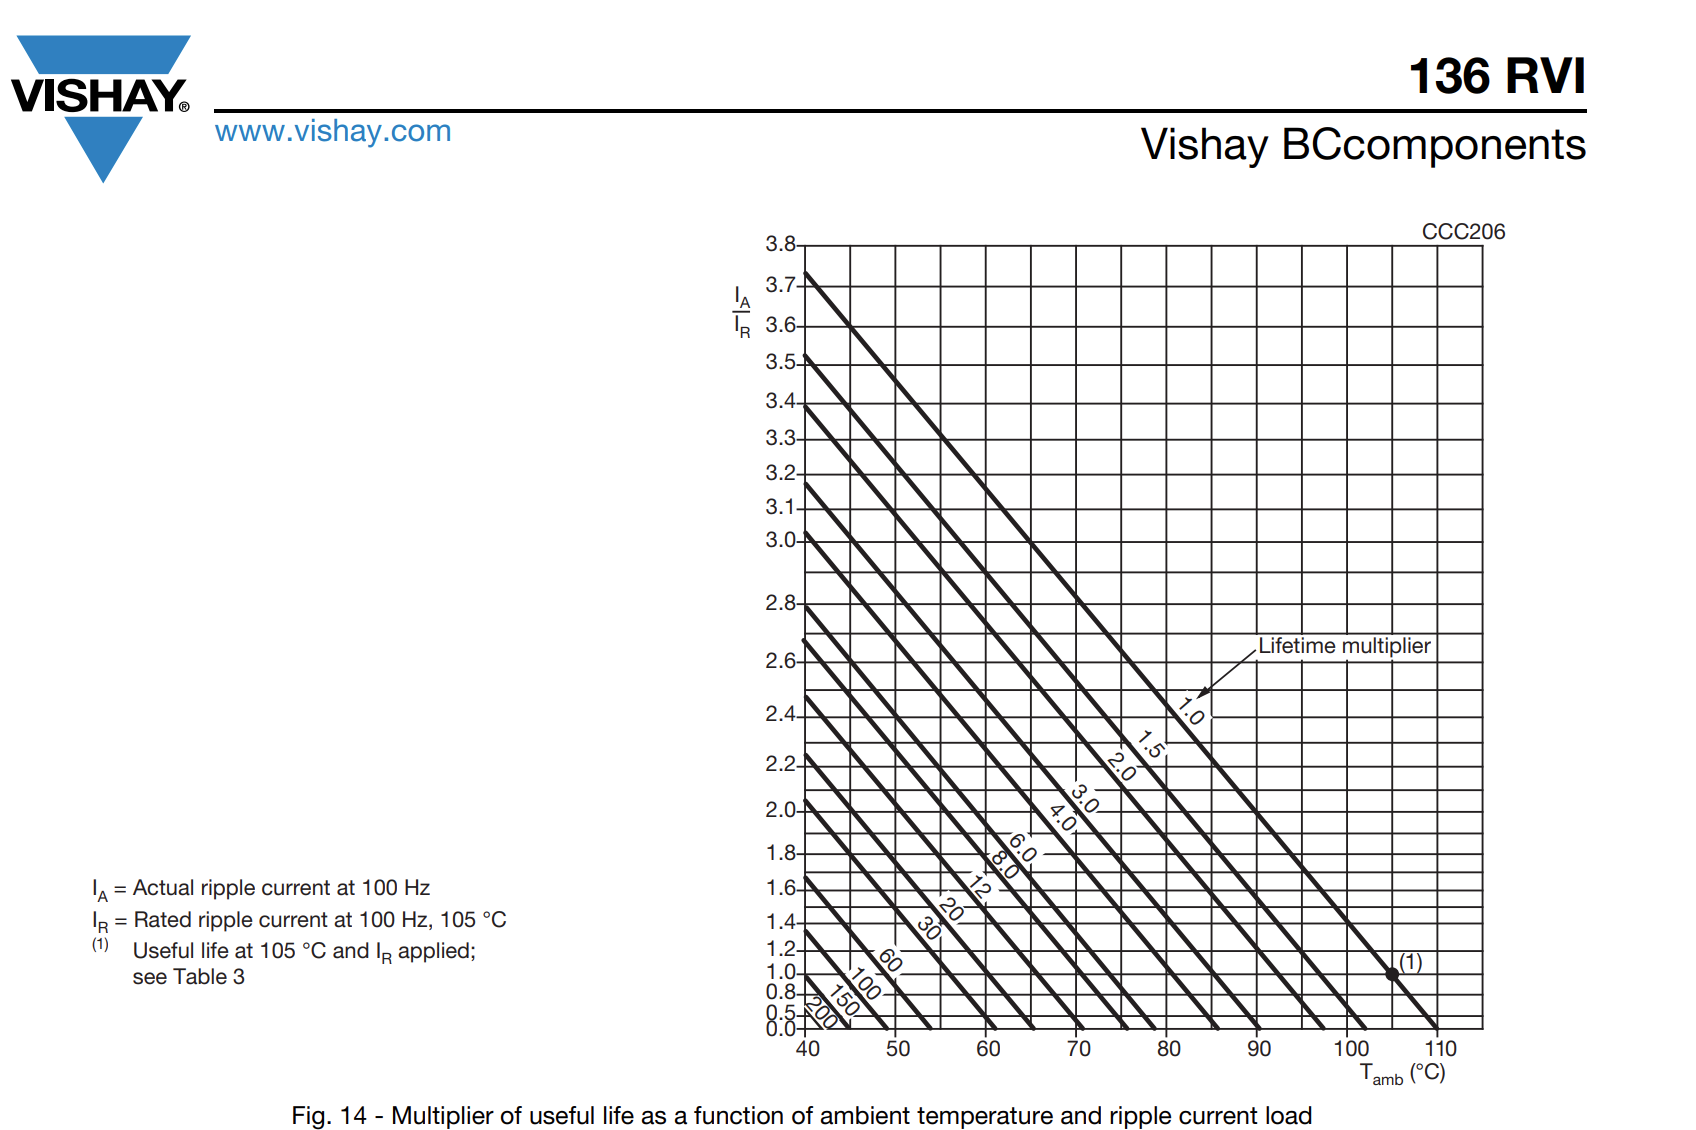

TAmb = 60°C 

IA = 1.1318 laut LTSPice

IR = 480mA

IA = 1.11318;
IR = 0.48;
mul = IA/IR 

mul = 2.3191

% Multiplier = 4.0 bei 2.31 IA/IR

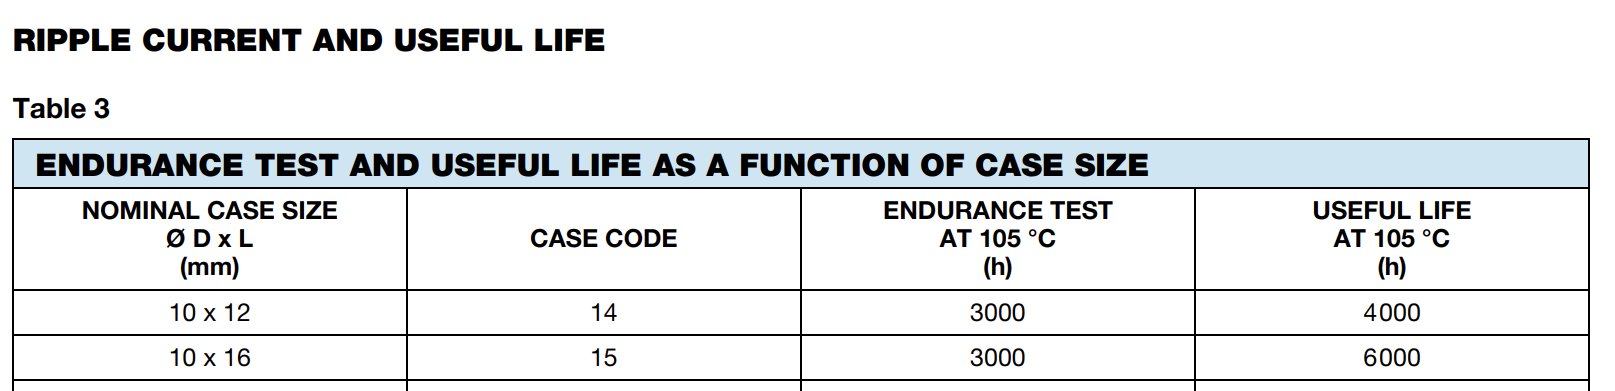

usefulLife = 4 * 4000 %h

usefulLife = 16000

usefulDays = usefulLife / 24

usefulDays = 666.6667